addpath('Kinematics')
addpath('Kinetics')
addpath('Control System')

supressed_print= evalc('run Nonlinear_Decoupled_EOMS_Try_2.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Derive the Partial Feedback Linearization Law for the Decoupled Nonlinear Dynamics and Run Simulation

## Partially Feedback Linearizing Torque Actuation

syms u_x

T_beta_FL_x = u_x/num_g_x(2) - num_f_x(2)/num_g_x(2)

$$T\_beta\_FL\_x = \left(-0.6491\,x^{2}-0.0564\right)\,u_{x}+\frac{\left(0.6491\,x^{2}+0.0564\right)\,\left(0.0732\,\sin\left(\beta \right)+1.4715\,x^{2}\,\sin\left(\beta \right)+0.0135\,{\dot{\beta }}^{2}\,x-0.0952\,x\,\cos\left(\beta \right)+0.1500\,{\dot{\beta }}^{2}\,x^{3}+0.0194\,\dot{\beta }\,x\,\dot{x}\right)}{0.2100\,x^{2}+0.0182}$$

## Partially Feedback Linearized System

NL_Dcpld_FLd_EOMs_x(x,x_dot,beta,beta_dot,u_x) = stateVec1_dot == expand(simplify(num_f_x + num_g_x*T_beta_FL_x))

$$NL\_Dcpld\_FLd\_EOMs\_x(x, x\_dot, beta, beta\_dot, u\_x) = \left[\begin{array}{c} \dot{x}=\dot{x}\\ \ddot{x}=u_{x}\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=151.6229\,\sin\left(\beta \right)-21.6383\,u_{x}+15.4560\,{\dot{\beta }}^{2}\,x \end{array}\right]$$

NL_Dcpld_FLd_EOMs_x_handle = function_handle with value:
    @(x,x_dot,beta,beta_dot,u_x)[x_dot;u_x;beta_dot;u_x.*(-2.163833075734158e+1)+sin(beta).*1.516228748068006e+2+beta_dot.^2.*x.*1.545595054095827e+1]


## Choose Virtual Input That Makes x Error States Decay to Zero

syms a b

First, define a characteristic polynomial in error dynamics. 

char_poly_ex_eqn = e_x_ddot + a*e_x_dot + b*e_x == 0

$$char\_poly\_ex\_eqn = a\,e_{\dot{x}}+b\,e_{x}+e_{\ddot{x}}=0$$

Substitute the error states for absolute states and setpoint states. 

char_poly_ex_eqn = subs(char_poly_ex_eqn, [e_x_ddot e_x_dot e_x ], [x_ddot_s - x_ddot, x_dot_s - x_dot , x_s - x])

$$char\_poly\_ex\_eqn = {\ddot{x}}_{s}-\ddot{x}-a\,\left(\dot{x}-{\dot{x}}_{s}\right)-b\,\left(x-x_{s}\right)=0$$

Isolate $\ddot{x}$ so it can be related to $u_x$ from the feedback linearization scheme.

xddot_from_char_poly = isolate(char_poly_ex_eqn, x_ddot)

$$xddot\_from\_char\_poly = \ddot{x}={\ddot{x}}_{s}-a\,\left(\dot{x}-{\dot{x}}_{s}\right)-b\,\left(x-x_{s}\right)$$

Choose stable Hurwitz polynomial coefficients for the error states characteristic polynomial.

roots_error_poly = poly([-20 -25])

roots_error_poly =      1    45   500


Get $u_x$ from $\ddot{x}$ of the characteristic error polynomial

u_x_eqn(x,x_dot,x_s, x_dot_s, x_ddot_s) = u_x == rhs(subs(xddot_from_char_poly ,[a b],roots_error_poly([2,3])))

$$u\_x\_eqn(x, x\_dot, x\_s, x\_dot\_s, x\_ddot\_s) = u_{x}=-500\,x+500\,x_{s}+{\ddot{x}}_{s}-45\,\dot{x}+45\,{\dot{x}}_{s}$$

View what $u_x$ does to the feedback linearized EOM

subs(NL_Dcpld_FLd_EOMs_x, u_x, rhs(xddot_from_char_poly))

$$ans(x, x\_dot, beta, beta\_dot, u\_x) = \left[\begin{array}{c} \dot{x}=\dot{x}\\ \ddot{x}={\ddot{x}}_{s}-a\,\left(\dot{x}-{\dot{x}}_{s}\right)-b\,\left(x-x_{s}\right)\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=151.6229\,\sin\left(\beta \right)-21.6383\,{\ddot{x}}_{s}+21.6383\,a\,\left(\dot{x}-{\dot{x}}_{s}\right)+21.6383\,b\,\left(x-x_{s}\right)+15.4560\,{\dot{\beta }}^{2}\,x \end{array}\right]$$

### Setpoint Parameters

r_sim = 5; % radius of circular trajectory [mm]
omega_sim =  pi/4; %angular frequency of circular trajectory 

des_traj_sym(t) = r_sim*sin(omega_sim*t);

### Overlay a fist order response so that the desired trajectory is smoothed out a bit

T = (2*pi/omega_sim)/5; %Time constant of the first order response that smooths out the trajectory
des_traj_sym(t) = (1 - exp(-(t/T)))*des_traj_sym;

### Find Derivatives of Trajectory

des_traj_sym_dot(t) = diff(des_traj_sym(t),t)

$$des\_traj\_sym\_dot(t) = 3.1250\,{\mathrm{e}}^{-0.6250\,t}\,\sin\left(0.7854\,t\right)-3.9270\,\cos\left(0.7854\,t\right)\,\left({\mathrm{e}}^{-0.6250\,t}-1\right)$$

des_traj_sym_ddot(t) = diff(des_traj_sym_dot(t),t)

$$des\_traj\_sym\_ddot(t) = 4.9087\,{\mathrm{e}}^{-0.6250\,t}\,\cos\left(0.7854\,t\right)-1.9531\,{\mathrm{e}}^{-0.6250\,t}\,\sin\left(0.7854\,t\right)+3.0843\,\sin\left(0.7854\,t\right)\,\left({\mathrm{e}}^{-0.6250\,t}-1\right)$$

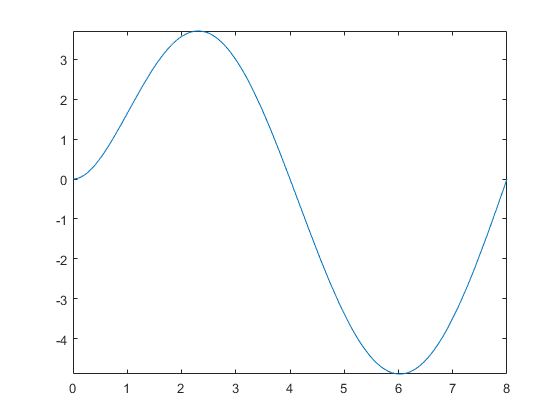

fplot(des_traj_sym) 
xlim([0 2*pi/omega_sim]);

des_traj_handle = matlabFunction([des_traj_sym(t),des_traj_sym_dot(t),des_traj_sym_ddot(t)])

des_traj_handle = function_handle with value:
    @(t)[sin((t.*pi)./4.0).*(exp(t.*(-5.0./8.0))-1.0).*-5.0,exp(t.*(-5.0./8.0)).*sin((t.*pi)./4.0).*(2.5e+1./8.0)-pi.*cos((t.*pi)./4.0).*(exp(t.*(-5.0./8.0))-1.0).*(5.0./4.0),exp(t.*(-5.0./8.0)).*sin((t.*pi)./4.0).*(-1.25e+2./6.4e+1)+pi.^2.*sin((t.*pi)./4.0).*(exp(t.*(-5.0./8.0))-1.0).*(5.0./1.6e+1)+pi.*exp(t.*(-5.0./8.0)).*cos((t.*pi)./4.0).*(2.5e+1./1.6e+1)]


## Simulate the Controller

Create an anonymous function handle for the equations of motion - compatibility with ODE45 

Create a MATLAB function handles to hand the dynamic equations to the EOM function

NL_Dcpld_FLd_EOMs_x_handle = matlabFunction(rhs(NL_Dcpld_FLd_EOMs_x))

NL_Dcpld_FLd_EOMs_x_handle = function_handle with value:
    @(x,x_dot,beta,beta_dot,u_x)[x_dot;u_x;beta_dot;u_x.*(-2.163833075734158e+1)+sin(beta).*1.516228748068006e+2+beta_dot.^2.*x.*1.545595054095827e+1]


u_x_handle = matlabFunction(rhs(u_x_eqn))

u_x_handle = function_handle with value:
    @(x,x_dot,x_s,x_dot_s,x_ddot_s)x.*(-1.0./5.0e+1)-x_dot.*(3.0./1.0e+1)+x_dot_s.*(3.0./1.0e+1)+x_ddot_s+x_s./5.0e+1



FL_EOM_fun_handle = @(t,state)FL_EOM_fun(t,state,des_traj_handle,NL_Dcpld_FLd_EOMs_x_handle,u_x_handle);

%Specify simulation time
tspan = [0 2*pi/omega_sim];

%Specify initial conditions
x0 = [0 0 0 0]'; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system

options = odeset('RelTol',1e-12);
[tout, xout] = ode45(FL_EOM_fun_handle, tspan, x0, options );

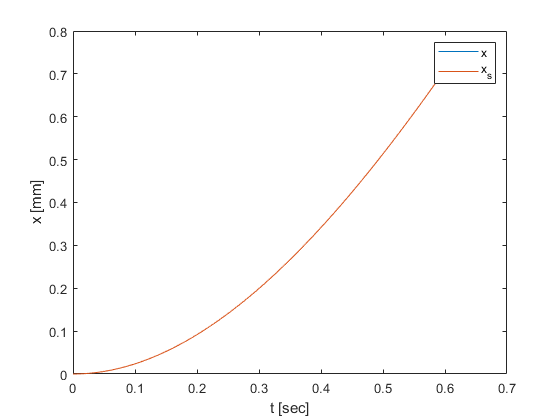

traj_out = des_traj_handle(tout);

figure
plot(tout, xout(:,1), tout, traj_out(:,1))
legend('x', 'x_s')
xlabel('t [sec]')
ylabel('x [mm]')

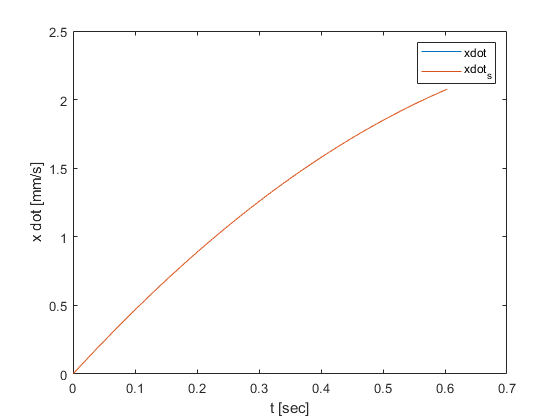


figure
plot(tout, xout(:,2), tout, traj_out(:,2))
legend('xdot', 'xdot_s')
xlabel('t [sec]')
ylabel('x dot [mm/s]')

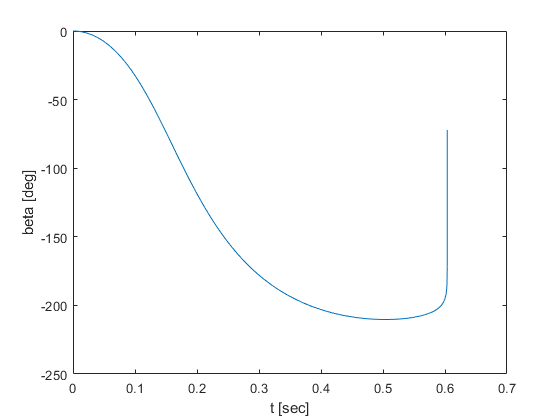


figure
plot(tout, rad2deg(xout(:,3)))
xlabel('t [sec]')
ylabel('beta [deg]')

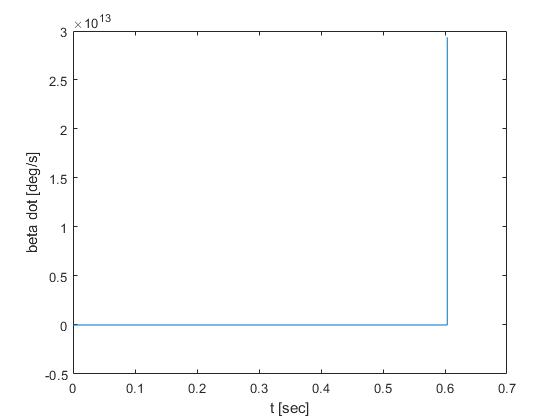


figure
plot(tout, rad2deg(xout(:,4)))
xlabel('t [sec]')
ylabel('beta dot [deg/s]')

xlim([0 5e-3])

function xdot = FL_EOM_fun(t,state,des_traj_handle,NL_Dcpld_FLd_EOMs_x_handle,u_x_handle)

x = state(1);
x_dot = state(2);
beta = state(3);
beta_dot = state(4);

traj = des_traj_handle(t);

u_x = u_x_handle(x, x_dot, traj(1), traj(2), traj(3));

xdot = NL_Dcpld_FLd_EOMs_x_handle(x, x_dot, beta, beta_dot, u_x);


end